clear all;
power = [100:100:1000]';
resistance = [300;150;100;75;60;50;42.86;37.5;33.33;30];
input = [116.1; 221.4; 329.1; 432.6; 537.0; 641.7; 720.0; 834.0; 930.0; 1041.0];
output = [100.1; 198.7; 302.2; 406.3; 510.1; 611.2; 690.6; 799.6; 892.3; 1008.1];
I_peak = [0; 0; 0; 0; 0; 2.96; 3.3; 3.87; 4.37; 5.08];
lost = [];
efficiency = [];

for c = 1:numel(input)
    m = input(c) - output(c);
    n = output(c)/input(c)*100;
    lost = vertcat(lost,m);
    efficiency = vertcat(efficiency,n);
end
lost;
efficiency;

T = table(power,resistance,input,output,lost,efficiency)

T = 10×6 table
    power    resistance    input    output    lost    efficiency
    _____    __________    _____    ______    ____    __________

     100         300       116.1     100.1      16      86.219  
     200         150       221.4     198.7    22.7      89.747  
     300         100       329.1     302.2    26.9      91.826  
     400          75       432.6     406.3    26.3       93.92  
     500          60         537     510.1    26.9      94.991  
     600          50       641.7     611.2    30.5      95.247  
     700       42.86         720     690.6    29.4      95.917  
     800        37.5         834     799.6    34.4      95.875  
     900       33.33         930     892.3    37.7      95.946  
    1000          30        1041    1008.1    32.9       96.84  


efficiency_avr = mean(efficiency)

efficiency_avr = 93.6528

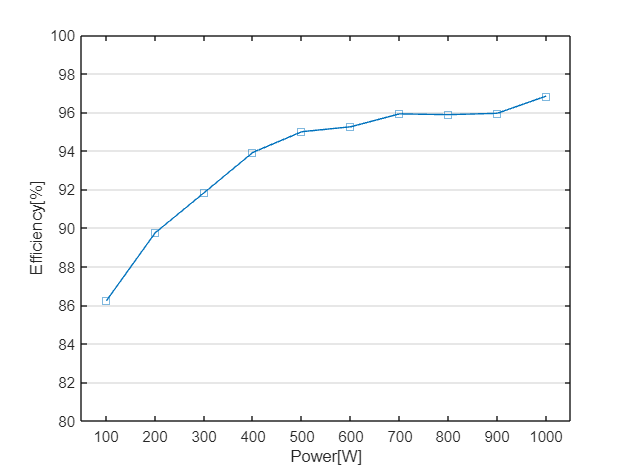

plot(power,efficiency,"-square")
axis([50 1050 80 100]);
xlabel("Power[W]")
ylabel("Efficiency[%]")

ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';